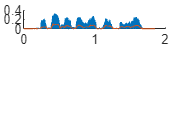

函数或变量 'legennd' 无法识别。

close('all'); clear; clc;

f_name = 'C_01_02.wav';
[x, fs] = audioread(f_name);
L = length(x);
t = (0:L-1)/fs;
x = abs(x);

cutoff = [100 200 700];
f531 = figure;
figure(f531)
for i = 1:length(cutoff)
    subplot(length(cutoff), 1, i);
    [b, a] = butter(2, cutoff(i)/(fs/2));
    x_f = filter(b, a, x);
    hold on;
    plot(t, x, t, x_f);
    legend('original audio', 'envelope')
    xlabel('t');
    title(sprintf('order 2 cutoff %dHz', cutoff(i)))
end

%% part2
order = [2, 6];
f532 = figure;
figure(f532)
for i = 1:length(order)
    subplot(length(order), 1, i);
    [b, a] = butter(order(i), 200/(fs/2));
    x_f = filter(b, a, x);
    plot(t, x, t, x_f);
    legennd('orginal audio', 'envelope');
    title(sprintf('Order: %d, Cutoff freq: 200Hz',order(i)));
end
%% tes

order = 1:2:10;
figure; hold('on');
legen = repmat("", 1, length(order));
for i = 1:length(order)
    [b, a] = butter(order(i), 0.5);
    [h, w] = freqz(b, a);
    plot(w, abs(h));
    legen(i) = sprintf('order=%d',order(i));
end
legend(legen); xlabel('\omega'); xlabel('Amplitude');
grid('on'); axis([0 pi 0 1]);
set(gca,'XTick', 0:pi/4:pi, 'XTickLabel',{'0','\pi/4','\pi/2','3\pi/4','\pi'});

cutoff = 100:200:700;
figure; hold('on');
legen = repmat("", 1, length(cutoff));
for i = 1:length(cutoff)
    [b, a] = butter(2, cutoff(i)/(fs/2));
    [h, w] = freqz(b, a);
    plot(w, abs(h));
    legen(i) = sprintf('cutoff=%d',cutoff(i));
end
legend(legen); xlabel('\omega'); xlabel('Amplitude');
grid('on'); axis([0 pi 0 1]);
set(gca,'XTick', 0:pi/4:pi, 'XTickLabel',{'0','\pi/4','\pi/2','3\pi/4','\pi'});
